clear ; close all; clc

**4.7**

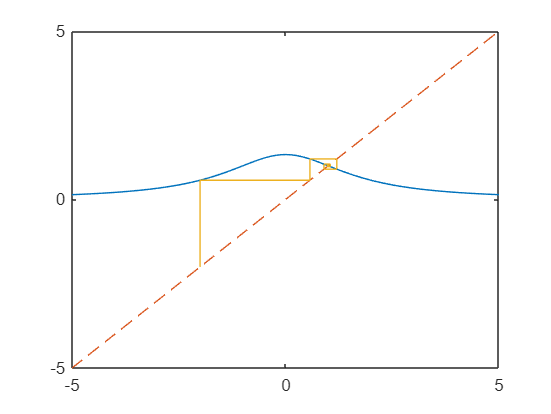

toleration: 0.001
Iterations: 14


a =    0.999902395543835


b =   -2.000000000000000   0.571428571428571   1.202453987730061   0.899706238412502   1.050014468881675   0.975008013288769   1.012494017729208   0.993753233402764   1.003123352733210   0.998438327436115   1.000780835805491   0.999609582156741   1.000195208914189   0.999902395543835


[a, b] = fixedpoint(@(x) x^3+3*x-4,@(x) 4/(x^2+3),-2,1e-3,100)

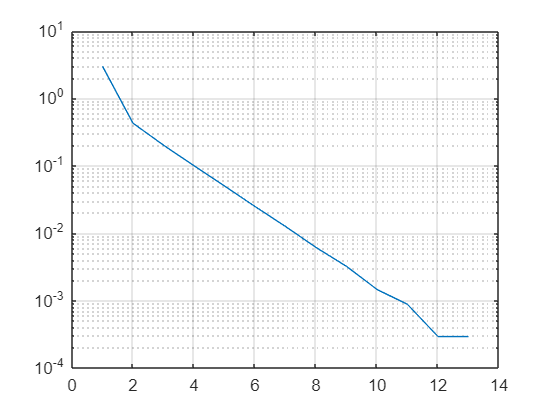


semilogy(abs(b-a))
grid on

**4.8**

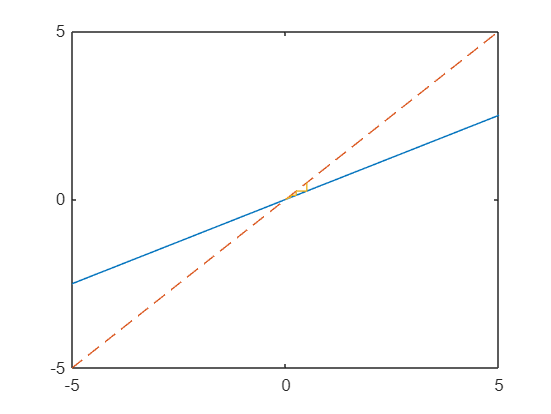

toleration: 1e-21
Iterations: 35


answer =      2.910383045673370e-11


history =    0.500000000000000   0.250000000000000   0.125000000000000   0.062500000000000   0.031250000000000   0.015625000000000   0.007812500000000   0.003906250000000   0.001953125000000   0.000976562500000   0.000488281250000   0.000244140625000   0.000122070312500   0.000061035156250   0.000030517578125   0.000015258789062   0.000007629394531   0.000003814697266   0.000001907348633   0.000000953674316   0.000000476837158   0.000000238418579   0.000000119209290   0.000000059604645   0.000000029802322   0.000000014901161   0.000000007450581   0.000000003725290   0.000000001862645   0.000000000931323   0.000000000465661   0.000000000232831   0.000000000116415   0.000000000058208   0.000000000029104


[answer, history] = newton(@(x) x^2,0.5,1e-21,100)

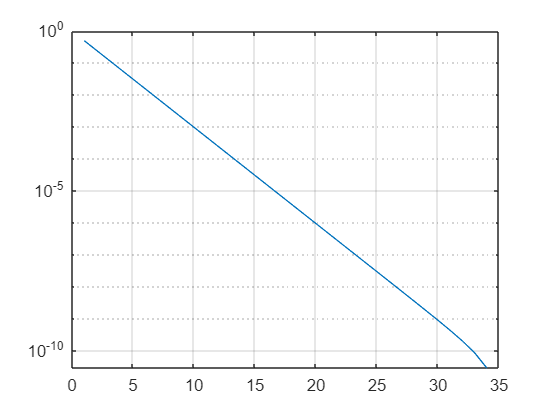


semilogy(abs(history-answer))
grid on

**4.9**

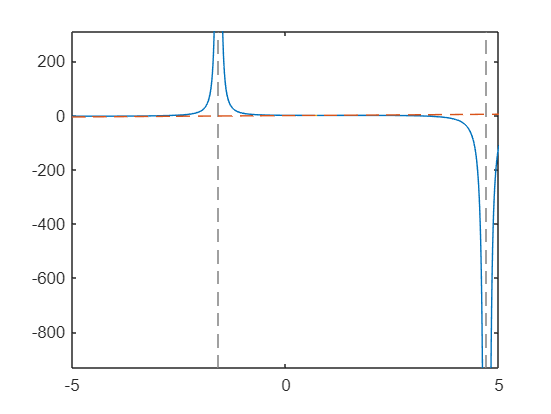

toleration: 1e-10
Iterations: 4


ans =    0.739085133215161


newton(@(x) cos(x)-x,0.7,1e-10,100) % Change in function fixedpoint.m

**4.11 4.12**

secant(@(x) 1*x^3+ 3*x - 4,0,3,0.001,100)

ans =    1.000045921152483


**4.13 **See in newton.m

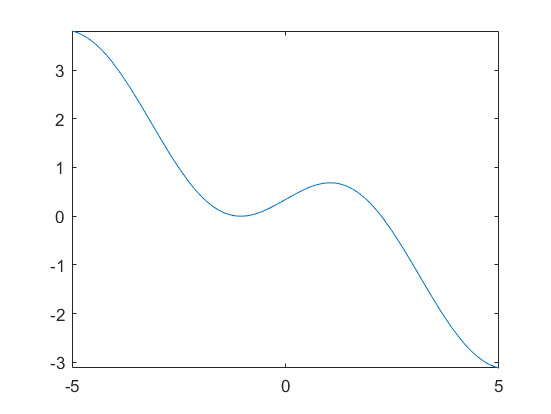

f = @(x) sin(x) - x/2 - pi/6 + sqrt(3)/2;
fplot(f)

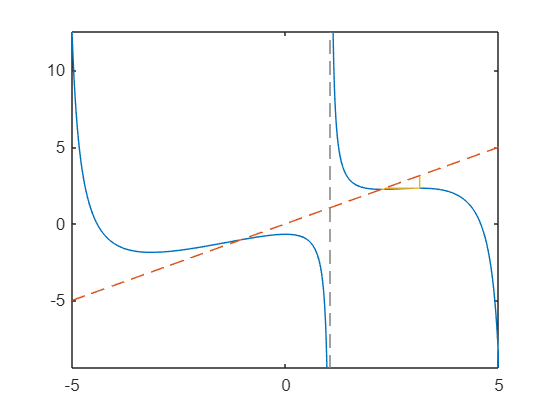

toleration: 1e-10
Iterations: 5


ans =    2.246005589298469


newton(f, pi, 1e-10,200 )

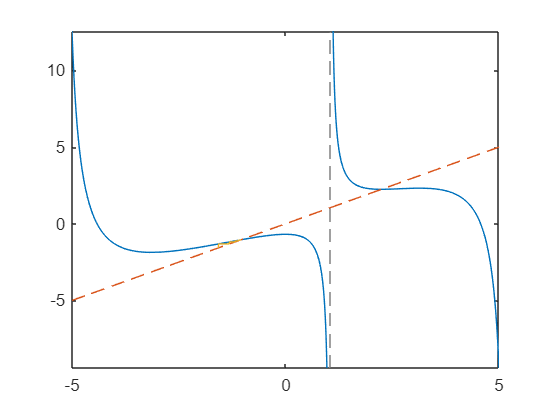

toleration: 1e-10
Iterations: 17


ans =   -1.047206078066725


newton(f, -pi/2, 1e-10,200 )